# Sampling distribution of the mean

Let us define a population $X \sim \mathcal{N}(170, 10^2)$

mu = 170;
sigma = 10;

We are creating 5000 samples, 5 times. And then calculate the mean of each of these samples.

Nsim = 5000;
mean5 = mean(mu + sigma*randn(5,Nsim),1)

mean5 =   167.4428  171.1712  168.1443  170.6141  177.4150  173.4446  165.9756  170.5647  173.8719  168.4996  175.0212  172.0672  178.9126  167.2559  173.2354  164.7347  165.6661  164.6621  164.9895  168.4013  173.9225  169.3757  169.0124  170.1081  164.2017  165.0337  164.9473  169.3098  173.8862  164.2414  168.9827  158.1182  170.0906  180.4195  169.7307  169.5712  169.8210  170.1712  167.6440  175.2240  170.9522  173.8727  168.7311  170.6827  175.8497  166.3102  177.1732  169.9809  175.0905  179.3457


We repeat this, but 20 times instead of 5:

mean20 = mean(mu + sigma*randn(20,Nsim),1)

mean20 =   169.3384  171.2794  172.8859  166.2833  172.1773  166.4724  167.8941  167.1910  169.9332  167.6155  168.6489  175.1761  167.0546  168.7623  170.9739  172.6579  169.5251  167.5317  170.3336  169.3851  168.4924  171.4860  171.1492  171.6286  170.2503  167.6553  172.4209  172.0632  171.0891  173.4826  174.0825  166.7432  167.7301  167.9934  171.9402  168.4975  169.7514  168.2074  169.7490  171.7022  169.3643  168.3123  170.3281  168.3188  168.9780  176.9958  170.2906  170.4992  170.2523  166.3935


Let's plot these:

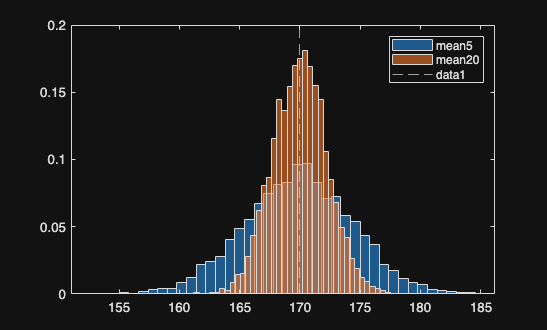

histogram(mean5,40,'Normalization','pdf');
hold on
histogram(mean20,40,'Normalization','pdf')
xline(mu,'--')
legend

We observe that the $n = 20$ distribution becomes narrower.

This is because averages become more stable as sample size increase.

# Standard Error

SE describes the variation among sample means.


$$\text{SE} = \frac{\sigma}{\sqrt{n}}$$


fprintf('Theoretical SE when n = 5 is %.2f\n',sigma/sqrt(5));

Theoretical SE when n = 5 is 4.47


fprintf('Theoretical SE when n=20 is %.2f\n',sigma/sqrt(20));

Theoretical SE when n=20 is 2.24


# 95% Confidence interval

Let us take a fresh sample.

sample = [166 168 170 172 174]

sample =    166   168   170   172   174


n = length(sample);
xbar = mean(sample)

xbar = 170

SE = std(sample)/sqrt(n)

SE = 1.4142

Note that the population standard deviation $\sigma$ is unknown. We only know the sample standard deviation $s$.

In scenarios like this, we use the $t$-distribution for calculating the confidence interval.

Here, we have $n = 5$ samples, there degree of freedom $df = n - 1 = 4$ 

The value of the $t$-distribution with 4 degrees of freedom such that 97.5% of the probability is below it is `2.776.`

tcrit = 2.776;
CI = xbar + [-1 1]*tcrit*SE

CI =   166.0741  173.9259



fprintf('Sample mean = %.2f\n',xbar)

Sample mean = 170.00


fprintf('SE = %.2f\n',SE)

SE = 1.41


fprintf('95%% CI = [%.2f, %.2f]\n',CI(1),CI(2))

95% CI = [166.07, 173.93]
